# **CAN - Working with J1939**

This example demonstrates sending and receiving J1939 parameter groups via a loopback connection of two CAN ports. Currently this example can be used with the IO602, IO603 and the IO691. 

The example performs data transfer with a loopback, by sending CAN messages from channel 1 to channel 2. The following blocks are used: [J1939 Network Configuration](https://mathworks.com/help/slrealtime/io_ref/j1939networkconfiguration.html), [J1939 Node Configuration](https://mathworks.com/help/slrealtime/io_ref/j1939nodeconfiguration.html), [J1939 CAN Transport Layer](https://www.mathworks.com/help/slrealtime/io_ref/j1939cantransportlayer.html), [J1939 Transmit](https://www.mathworks.com/help/slrealtime/io_ref/j1939transmit.html) and [J1939 Receive](https://www.mathworks.com/help/slrealtime/io_ref/j1939receive.html).

This example demonstrates the following modes and features:

- Sending and receiving CAN messages in FIFO mode

- J1939 network and node configuration

- Using the J1939 CAN Transport Layer

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with an IO602, IO603 or an IO691 CAN I/O module installed

- 1x CAN Loopback test cable with terminator resistor (120 Ω)

### Connection Diagram

To run this example, the CAN channel 1 and channel 2 must be connected with a terminated CAN cable. As this example can be executed either with an IO602, IO603 or an IO691, refer to the pin mapping for your CAN I/O module to connect channel 1 and channel 2:

[IO602-2 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_2_pin_mapping)/[IO602-4 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_4_pin_mapping)/[IO603 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io603_pin_mapping)/[IO691 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io691_pin_mapping)

## Open and Configure the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_CAN_J1939Loopback';
open_system(modelName);

### Select CAN I/O Module

In the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block, select the specific CAN I/O module that you are using. A unique **Module ID** is set in every [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to link the [CAN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_read) and [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) blocks in the rest of the model to this Setup block. If there is only one IO602, IO603 or IO691 in the target, the **Module ID** can always remain at 1.

 
% open the CAN setup block to select your CAN I/O module
speedgoat.model.highlight([modelName '/CAN_Setup'],'Parameter','moduleType');

### Specify CAN channels

After selecting the correct CAN I/O module, channel 1 and channel 2 will be configured for the CAN operating mode. You can do this with the dropdown in the mask or with the following code section. Unused CAN channels can be disabled.

 
% configure CAN channel 1 and 2 to CAN
set_param([modelName '/CAN_Setup'],'canChn1','CAN (HS)');
set_param([modelName '/CAN_Setup'],'canChn2','CAN (HS)');

When a channel is enabled, the baud rate can be configured in the tab that is shown for each channel.

## Model Description

The model is divided into four sections.

You have already used the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to configure the CAN I/O module with its channels. The remaining items to configure are the J1939 network and nodes, and the areas to read and write the CAN messages. The J1939 data is sent from CAN channel 1 to channel 2. 

The J1939 blocks used in this example are available in the **Simulink Library Browser** under *Simulink Real-Time/J1939*. They can also be found in the following block library: 

### J1939 Configuration

 
% highlight the area for the J1939 Configuration
speedgoat.model.highlight([modelName '/J1939 Configuration - Channel 1']);

To send and receive J1939 messages over CAN, a database file (.dbc) is required and this file must be specified in the [J1939 Network Configuration](https://mathworks.com/help/slrealtime/io_ref/j1939networkconfiguration.html) block. As multiple J1939 networks can be used in one Simulink model, a unique configuration name must be defined. As this example demonstrates a loopback with two nodes, two J1939 networks must be configured.  "**Config1**" is used for the configuration name used with channel 1 and "**Config2**" for channel 2. The database file is "**J1939Database.dbc**" for both configurations. This J1939 database file is included with this example and the database contains multiple nodes. In this loopback, the two nodes have one Rx and one Tx message each (Node1: EMS, Node2:TECU).

Specifying the database file in the [J1939 Network Configuration](https://mathworks.com/help/slrealtime/io_ref/j1939networkconfiguration.html) block will allow you to select the Parameter Groups (PG) of this database in all the blocks that are linked through references to the same configuration name. 

### Pack and Unpack J1939 Messages

The [J1939 Transmit](https://www.mathworks.com/help/slrealtime/io_ref/j1939transmit.html) and [J1939 Receive](https://www.mathworks.com/help/slrealtime/io_ref/j1939receive.html) blocks are used to select which J1939 messages should be sent and received. The two blocks feature the **Config name **and **Node name** parameters to reference the database file specified in the [J1939 Network Configuration](https://mathworks.com/help/slrealtime/io_ref/j1939networkconfiguration.html) block. When a node is selected, all the J1939 PGs assigned to this node can be selected from a dropdown in the blocks. The signal table is automatically populated based on the selected message. 

In this example, the **ET1_EMS(65262)** PG is sent from the **EMS** node to the **TECU **node. Use the [J1939 Transmit](https://www.mathworks.com/help/slrealtime/io_ref/j1939transmit.html) block to select this PG. The signals from this message are available on the inputs of this block.

 
% highlight J1939 Transmit block parameters
speedgoat.model.highlight([modelName '/J1939 Transmit1'],'Parameter',{'ConfigName','NodeName','PGList'});

This priority setting prevents multiple PGs transmitting on the same bus at the same time. If a conflict occurs, the priority group with lower priority (higher value) will refrain from transmitting. 

The [J1939 Transmit](https://www.mathworks.com/help/slrealtime/io_ref/j1939transmit.html) block is set to queue data for transmission at each timestep when the **Trigger** port is enabled. For this example, a pulse generator sends a high pulse every 50 milliseconds. 

On the receiving end, in the [J1939 Receive](https://www.mathworks.com/help/slrealtime/io_ref/j1939receive.html) block, the same parameters must be set. Additional settings to configure source and destination addresses can also be defined. 

### Transmitting and Receiving the CAN messages

So far the J1939 PGs have been configured, but the CAN messages are not yet linked to a physical CAN interface. To transmit and receive the J1939 CAN messages, a [J1939 CAN Transport Layer](https://www.mathworks.com/help/slrealtime/io_ref/j1939cantransportlayer.html) block is used, one for each CAN channel. These blocks handle the J1939 messaging and are used for the transmission and reception of the CAN messages. The protocol stack handles both the regular J1939 communication and the (optional) transport protocol functionalities. 

 
% highlight J1939 CAN Transport Layer blocks
speedgoat.model.highlight([modelName '/J1939CANTransportLayer_Config1']);
speedgoat.model.highlight([modelName '/J1939CANTransportLayer_Config2']);

All the CAN messages received on this channel, and the count of the messages received must be connected to the inputs of this block. The [J1939 CAN Transport Layer](https://www.mathworks.com/help/slrealtime/io_ref/j1939cantransportlayer.html) block ensures that all the CAN messages linked with a PG specified in one of the [J1939 Receive](https://www.mathworks.com/help/slrealtime/io_ref/j1939receive.html) blocks are unpacked and the signals are then available on the outputs of the [J1939 Receive](https://www.mathworks.com/help/slrealtime/io_ref/j1939receive.html) block. This applies to all blocks using the same J1939 configuration name. 

The packed J1939 CAN messages (**CAN Msg**) and the actual number of CAN messages (**N**) are the block outputs. These two outputs are linked to a PG specified in the [J1939 Transmit](https://www.mathworks.com/help/slrealtime/io_ref/j1939transmit.html) blocks. Variable signal dimensions are not supported for code generation, therefore a predefined vector of the size 20 is used for the CAN message vector. With the number of CAN messages output (N), it is known how many CAN messages from the vector must be transmitted to the physical CAN bus.

Transmitting the CAN message containing the PGs can be done using a custom MATLAB Function and a [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block: 

 
% highlight CAN Write - Channel 1
speedgoat.model.highlight([modelName '/CAN Write - Channel 1'],'Open',true);

In this subsystem, the vector with the CAN messages is passed as a whole to the [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block. The number of CAN messages being transmitted at each sample step is controlled by the second input signal communicated by the [J1939 CAN Transport Layer](https://www.mathworks.com/help/slrealtime/io_ref/j1939cantransportlayer.html) block. This requires a custom MATLAB Function block to convert from a scalar to a vector for controlling the Transmission Control input of the CAN Write block.

To ensure the CAN messages received can be processed by the [J1939 CAN Transport Layer](https://www.mathworks.com/help/slrealtime/io_ref/j1939cantransportlayer.html) block, all the CAN messages received are stored in a buffer vector. This is achieved with a do-while iteration subsystem:

 
% highlight CAN Read Loop - Channel 1
speedgoat.model.highlight([modelName '/CAN Read Loop - Channel 1'],'Open',true);

The do-while loop, together with the [CAN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_read) block in FIFO mode, ensures that within one sample step all CAN messages are read from the hardware buffer of the CAN I/O module. The CAN messages received are assigned to a vector with a fixed size of 501 by using the output **Iteration number** parameter of the [While Iterator](https://mathworks.com/help//simulink/slref/whileiterator.html) block and an [Assignment](https://mathworks.com/help/simulink/slref/assignment.html) block (501 is the size of the CAN I/O module hardware buffer and therefore the limit in terms of the number of CAN messages that can be received in one sample step.)

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
open_system(modelName); % go to top level
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download the real-time application to the target machine and set stop time
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   
set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Wait until the real-time application reaches the stop time of 10 seconds

### Results

Check the scopes for the [J1939 Receive](https://www.mathworks.com/help/slrealtime/io_ref/j1939receive.html) blocks to see if the loopback is working. The screenshots below show the expected outcome. 

You can change the parameters of the source signal blocks. Any changes should be reflected immediately. 

 
% open Simulink scopes
speedgoat.model.highlight([modelName '/Scope_TCFG2_TECU'],'Open',true);
speedgoat.model.highlight([modelName '/Scope_ET1_EMS'],   'Open',true);         

**CAN J1939 - Ch1 Read**

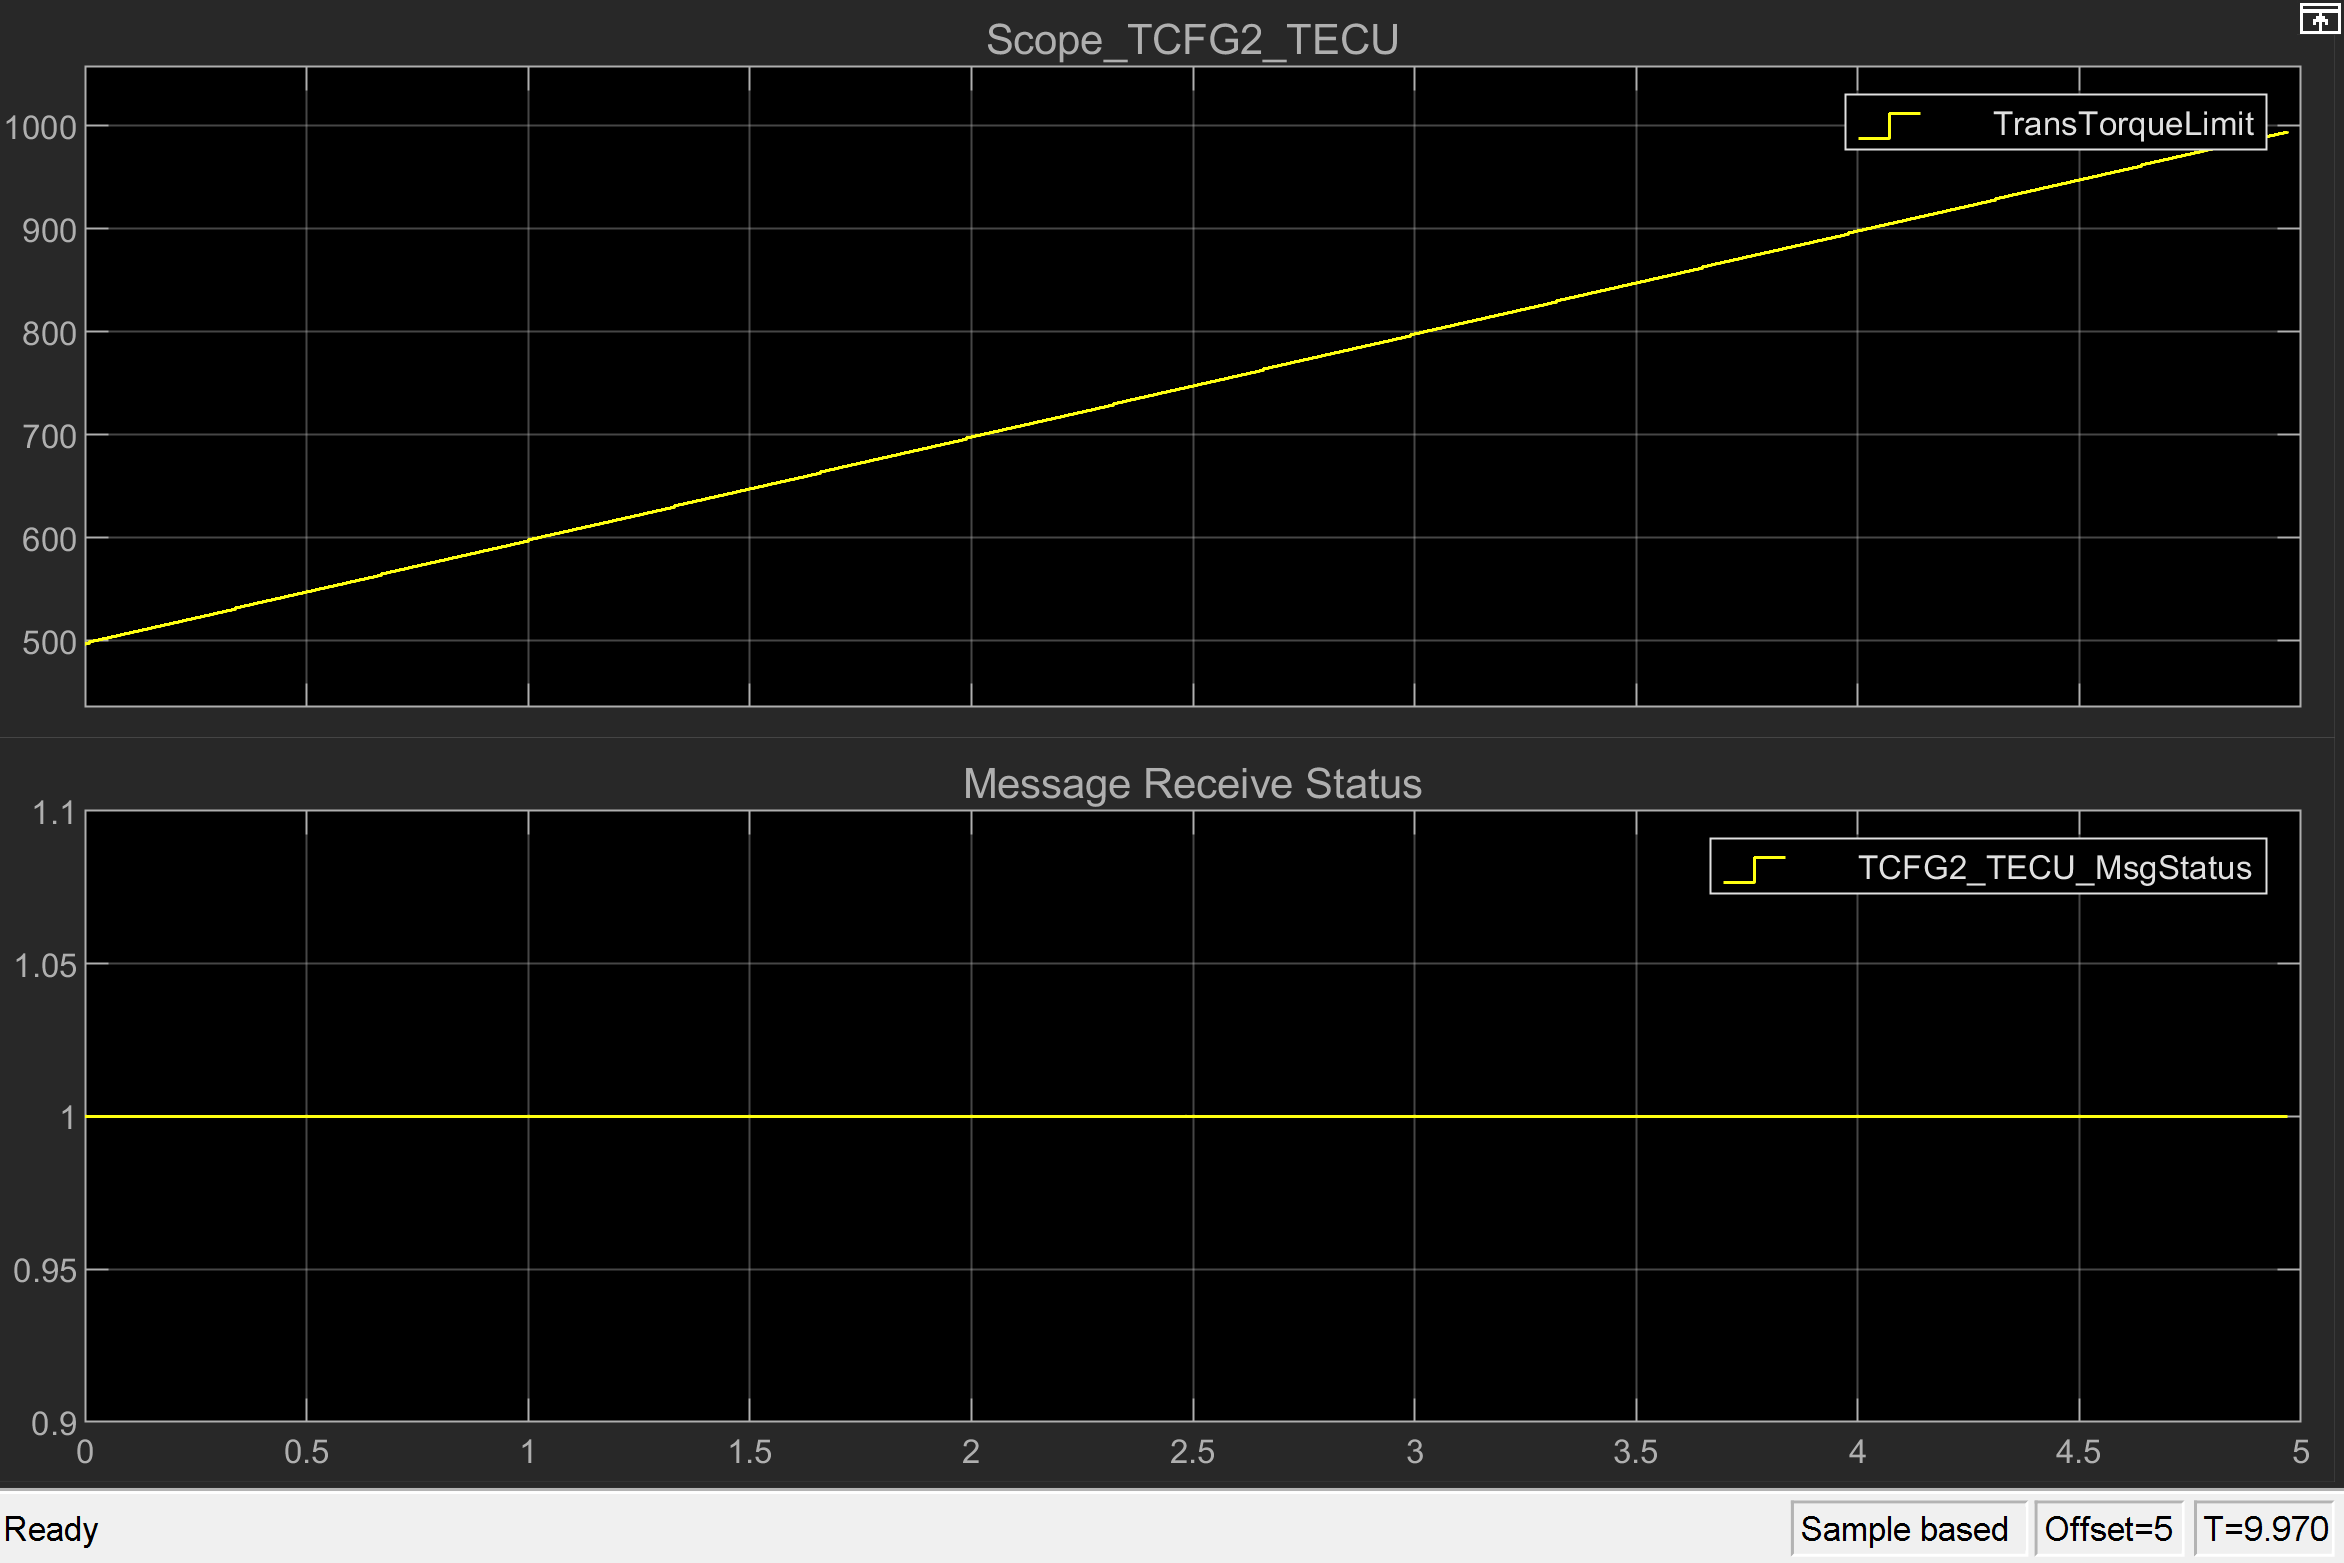

**CAN J1939 - Ch2 Read**

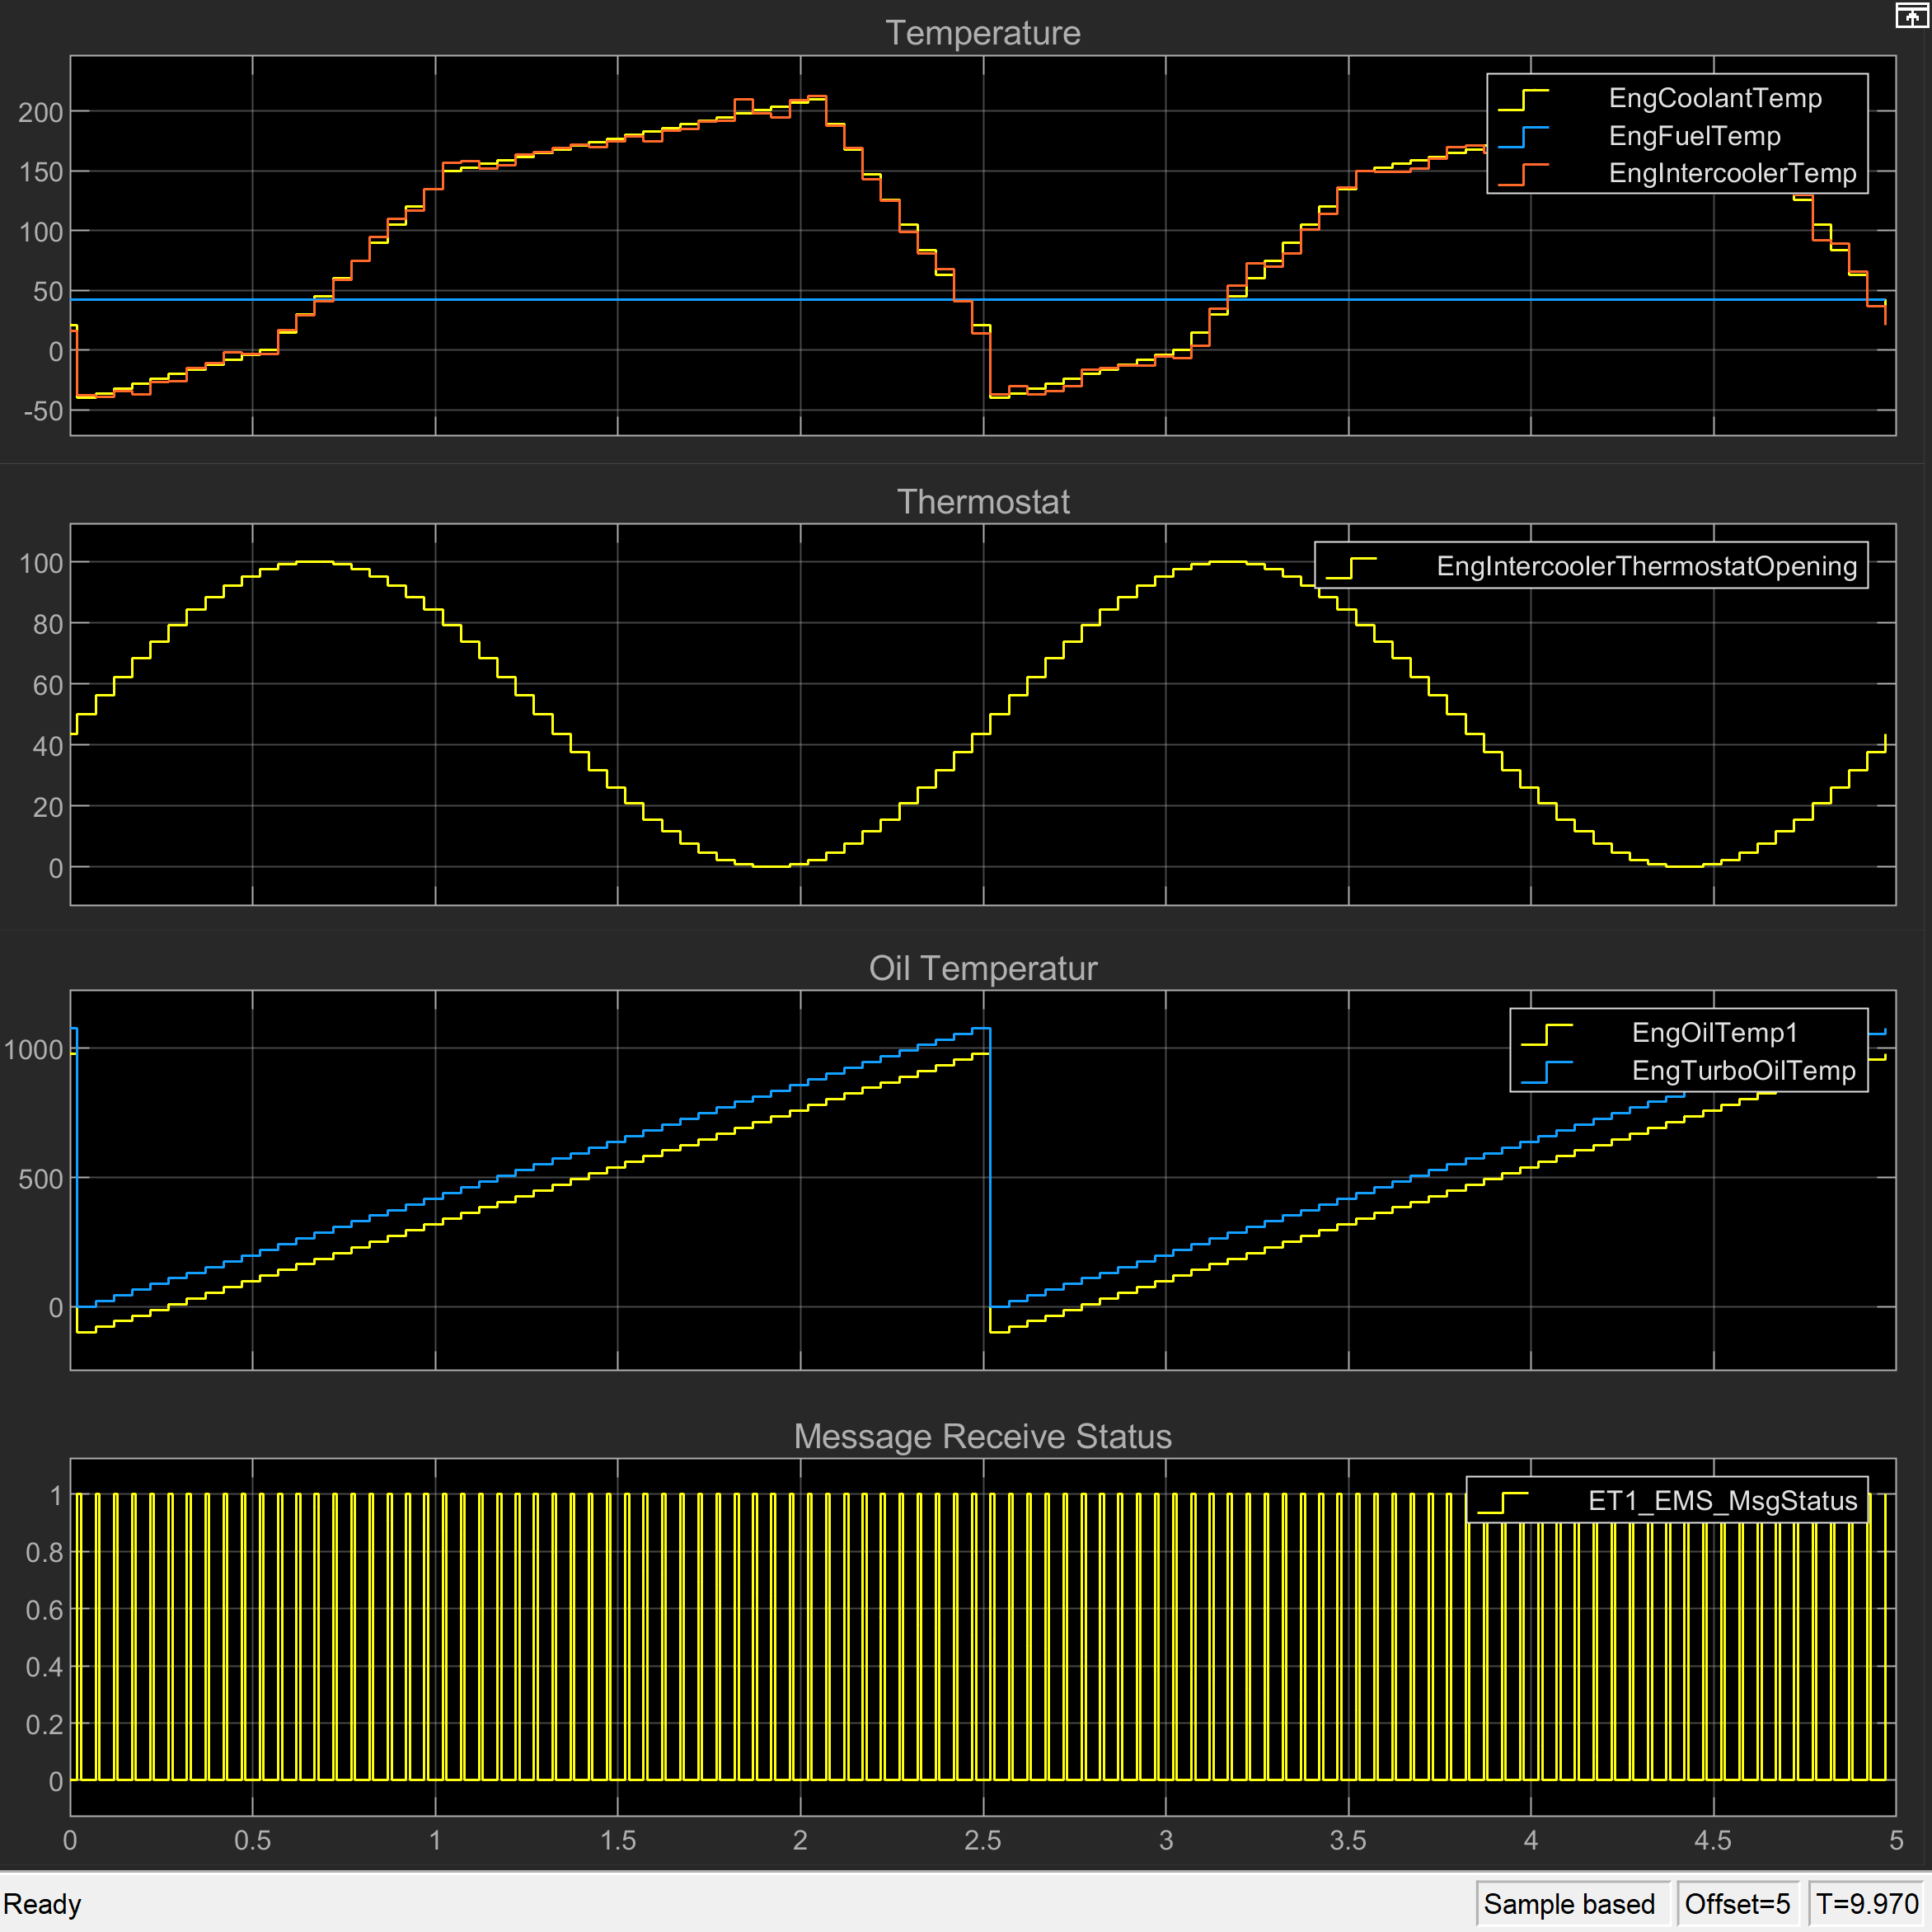

## Additional References

- [IO602/IO603/IO691 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa)

- [Simulink Real-Time - J1939 documentation page](https://mathworks.com/help/slrealtime/j1939.html)